# Exploring Functions

## Introduction

Plotting graphs is indispensable in science and engineering as a tool for communicating information and results. MATLAB provides an extensive set of commands that facilitate the creation of high-quality plots. 

In this activity we will explore the basic commands used to create and manipulate two-dimensional plots.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

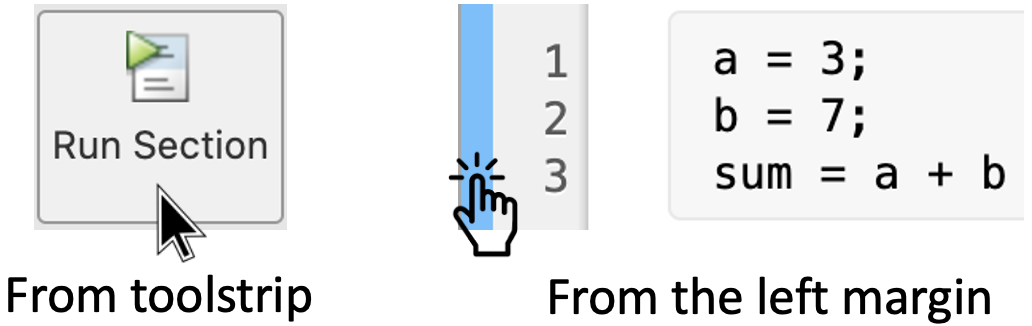

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. How to create a plot from a set of points

The `plot` command is used to create two-dimensional line plots. To plot a set of points $\left\lbrace \left(x_1 ,y_1 \right),\left(x_2 ,y_2 \right)\dots ,\left(x_n ,y_n \right)\right\rbrace$, we need to write [`plot(x,y)`](https://au.mathworks.com/help/matlab/ref/plot.html) where $x=\left(x_1 ,x_2 ,\dots ,x_n \right)$ is a vector containing the $x$-values of the points and $y=\left(y_1 ,y_2 ,\dots ,y_n \right)$ is a vector containing their corresponding $y$-values. 

Vectors are entered in MATLAB by typing the elements within square brackets `[]`. There are two types, row and column vectors. In this activity **we just need row vectors** which can be written using commas or spaces to separate the elements. For example, to plot the set of points $\left\lbrace \left(0,0\right),\left(1,1\right),\left(24\right),\left(3,9\right)\right\rbrace$, we need the code:

x = [0,1,2,3,4]    % Defines vector x = (0, 1, 2, 3, 4), domain
y = [0,1,4,9,16]    % Defines vector y = (1, 1, 4, 9, 16), range
plot(x,y);

Once you run the previous code, you will notice that MATLAB has joined the points with straight lines and has selected a sensible set of axes.

Looking at the graph, you will see that MATLAB has plotted each element of the vector `y` versus its corresponding element in the vector `x`. Accordingly, it is important that *these two vectors have the same length*, otherwise MATLAB returns an error. For example, if we had omitted the last element of "`x`" in the above example, then MATLAB would have returned the error message:

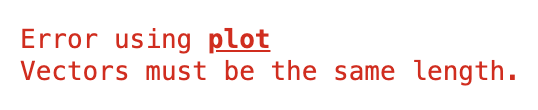

Try it yourself! Modify the previous code and re-run this section to see happens when you delete 4, the last term from `x = [0,1,2,3,4]`.

### 1.1 The colon operator "`:`" to create vectors

The [colon operator ":"](https://au.mathworks.com/help/matlab/ref/colon.html) is one of the most useful operators in MATLAB. It is used to create vectors, subscript arrays, and specify `for` iterations. In this case, we are interested in creating row vectors. 

For example, if you want to create a row vector, containing integers from 1 to 10 with an increment of one, then you write:

1:10

However, if you want to specify an increment value other than one, you can write for instance:

1:2:10       % Increment of 2
1:1/2:10     % Increment of one half
0:pi/4:pi    % You can use real numbers as well
100:-5:50    % This one is decreasing 5 units from 100 to 50

Run this section to see and analyse the different outputs.

## 2. How to plot functions `y = f(x)`

To plot the graph of a function, you need to take the following steps:

- Define `x`, by specifying the range of values for the variable `x`, for which the function is to be plotted

- Define the function, `y = f(x)`

- Call the plot command, as `plot(x,y)`

The following examples would demonstrate the concept.

### 2.1 Example 1 - Plotting one graph

Let us plot the simple function $y=x$ for the range of values for $x$ from 0 to 50, with an increment of 5. Run this section to see the plot:

x = 0:5:50    % Defines the domain as a row vector
y = x;        % Defines the range 
plot(x, y)

The colon operator "`:`" is used here to create row vectors of evenly-spaced numbers. The simplest use of the colon operator is to create a row vector of consecutive integers. You can also type 

`x = [0, 5, 10, 15, 20, 25, 30, 35, 40, 45, 50]`

but here it is more convenient to use the colon symbol. What do you think?

### 2.2 Example 2 - Plotting two graphs

Let us plot the function $y=x^2$. In this example, we will draw two graphs of the same function, with different values of increment. Note that as we decrease the increment, the graph becomes smoother.

x1 = -100:50:100;      % Domain with big increment 
x2 = -100:25:100;      % Domain with small increment
y1 = x1.^2;            % Range of x1
y2 = x2.^2;            % Range of x2
plot(x1, y1, x2, y2)

**Remark:** Here we are using row vectors (also known as *arrays*) which means that the operations *multiplication*, *division* and *exponentiation* must have the *period *"`.`" before each operator: `*, /, ^`. Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).

Modify the first two lines, in the previous code, so both plots are smooth. Then re-run this section to see the result. 

If you prefer to have two plots separately then replace `plot(x1, y1, x2, y2)` with the following two lines:

Try it yourself and re-run this section to see the result.

### 2.3 Example 3 - Plots using the command `linspace()`

To create row vectors, we can also use the command

[`linspace(x1, x2, n)`](https://au.mathworks.com/help/matlab/ref/linspace.html#d123e774529)

which generates $n$ points between `x1` and `x2 (including the end points)`. The spacing between them is

`(x2-x1)/(n-1)`.

This command is similar to the colon operator "`:`", but gives direct control over the number of points and always includes the endpoints. 

In the following example we will draw three different functions with the same domain using this command:

x = linspace(0, 2*pi, 1000);  % 1000 points between 0 and 2pi. What if n = 10?
y1 = sin(x);
y2 = sin(x - 0.25);
y3 = sin(x - 0.5);
plot(x, y1, '-.r', x, y2, '--g', x, y3, '-k')
legend('sin(x)', 'sin(x-0.25)', 'sin(x-0.5)')

For each pair of vectors in a `plot` command, we can add an additional argument to specify the **line style**, **marker symbol**, and **colour** used to plot the pair. To modify the presentation of a single graph, we use the command

`plot(x, y, LineSpec)`

where [`LineSpec`](https://au.mathworks.com/help/matlab/ref/linespec.html) is a string (i.e., some text surrounded by apostrophes (`'`)) that specifies the* line style*, *marker symbol *and *colour* of the graph. Some other values you can use are the following:

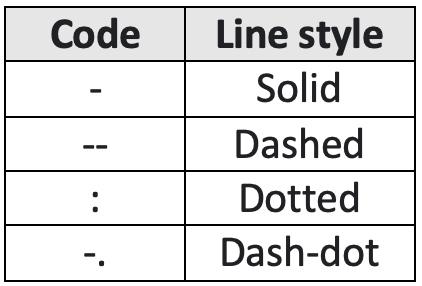   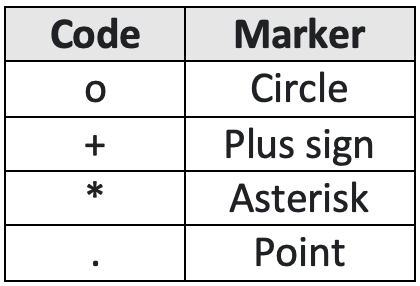    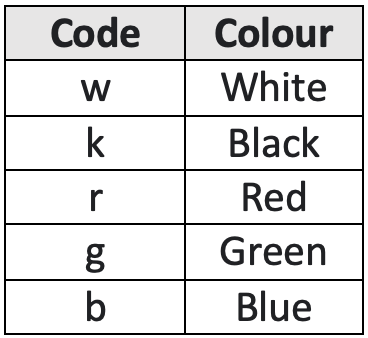

Finally, in order to identify each graph we added the command [`legend()`](https://au.mathworks.com/help/matlab/ref/legend.html), which creates a descriptive label for every graph.

Modify the `plot` command, in the previous code, to change the line style or colour. Also try to add a marker. Re-run your code to see the changes.

### 2.4 Example 4 - Adding Title, Labels, Grid Lines and Setting Axes

To provide a better presentation of your plots, MATLAB allows you to add **title**, **labels** along the x-axis and y-axis, **grid lines** and also to **adjust the axes.**

For example, run the following code:

x = linspace(0, 5, 1000);
y = exp(-1.5 * x).* sin(10 * x);
plot(x, y)
title('A model for a damped harmonic oscillator')
xlabel('x')
ylabel('exp(–1.5x)*sin(10x)')
grid on
axis([0 5 -1 1])

- The [`title()`](https://au.mathworks.com/help/matlab/ref/title.html) command allows you to put a title on the graph.

- The [`xlabel()`](https://au.mathworks.com/help/matlab/ref/xlabel.html) and [`ylabel()`](https://au.mathworks.com/help/matlab/ref/ylabel.html) commands generate labels along x-axis and y-axis.

- The [`grid on`](https://au.mathworks.com/help/matlab/ref/grid.html#d123e521561) command allows you to put the grid lines on the graph.

- Finally, the [`axis()`](https://au.mathworks.com/help/matlab/ref/axis.html#d123e65450) command allows you to set the axis scales. You can provide the minimum and maximum for x and y axis: `axis([xmin xmax ymin ymax])`

## 3. Hands on Practice

Let's practice what we just learned. 

### 3.1 Inverse functions

### Activity 1:

Consider the function


$$f\left(x\right)=\frac{1}{2}x^2 +3x-1$$
 

Notice that $f\left(x\right)$ is not a one-to-one function on $\left(-\infty ,\infty \right)$. Plot $f\left(x\right)$ on an closed interval $\left\lbrack a,b\right\rbrack$ where $f\left(x\right)$ is *one-to-one.*

Write your code here:

### Activity 2:

Plot the functions

$f\left(x\right)=\frac{x-3}{x-2}$   and  $g\left(x\right)=\frac{2x-3}{x-1}$

on the same axes, with the *x*-axis ranging from -4 to 4 and the *y*-axis raging from -10 to 10.

Write your code here:

**Hint:** Recall that the operation of *division* must have the period before the operator, that is "`./`". Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).

What do you notice? What do you wonder? Is $g$ the inverse of $f$ on the interval $\left\lbrack -4,4\right\rbrack$? How can you prove it?

### 3.2 Floor and Ceil functions

In mathematics and computer science, the **floor function** $\left\lfloor x\right\rfloor$ is the one that returns the *greatest* integer less than or equal to $x$. On the other hand, the **ceiling function** $\left\lceil x\right\rceil$ returns the *least* integer greater than or equal to $x$.

### Activity 3:

Use the built-in functions [`floor()`](https://au.mathworks.com/help/matlab/ref/floor.html) and [`ceil()`](https://au.mathworks.com/help/matlab/ref/ceil.html) to evaluate the following values:

- $\left\lfloor 25\ldotp 21\right\rfloor$, $\left\lfloor -31\ldotp 57\right\rfloor$, $\left\lfloor -\pi \right\rfloor$, $\left\lfloor e+1\right\rfloor$

- $\left\lceil 25\ldotp 21\right\rceil$, $\left\lceil -31\ldotp 57\right\rceil$, $\left\lceil -\pi \right\rceil$,$\left\lceil e+1\right\rceil$

Compare the results. What do you notice?

Write your code here:

### Activity 4:

Plot together the graphs of ${\left(-1\right)}^{\left\lfloor x\right\rfloor }$ and ${\left(-1\right)}^{\left\lceil x\right\rceil }$ on the same axes, with the *x*-axis ranging from -5 to 5 and the *y*-axis raging from -1.5 to 1.5. Use the commands from sections 2.3 and 2.4 to identify each graph in the same plot.

Write your code here:

**Hint:** Recall that the operation of *exponentiation* must have the period before the operator, that is "`.^`". Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).